# **Multi-objective Optimality in Metabolism, Practice using a breast cancer model**

**Identification of Cancer–associated Metabolic Vulnerabilities by Modeling Multi-objective Optimality in Metabolism**

Ziwei Dai1, Shiyu Yang4, Liyan Xu4, Hongrong Hu4, Kun Liao4, Jianghuang Wang4, Qian Wang2, Shuaishi Gao1, Bo Li4*, Luhua Lai1,2,3*

Practica realizada por Eduardo Ruiz Robles


initCobraToolbox(false); % Inicializar COBRA Toolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2025
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.39.5).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

**La practica posee bastante complejidad ya que involucra distintas funciones, calculos y adaptaciones a este modelo para poder calcular el conjunto de soluciones de pareto. Para un entendimiento claro leer el articulo publicado y el word 12964_2019_439_MOESM1_ESM.**

**Los graficos obtenidos fueron bastante similares a los obtenidos por Ziwei Dai1, et,al.**

**El objetivo es encontrar prooncogénes y oncogenes.**

**El analisis consiste en cerrar cierta reacción durante el calculo de soluciones de pareto y analizar un aumento o disminución en el limite superior e inferior. Si el limite superior disminuye a medida que aumenta la tasa de crecimiento, es una enzima supresora (oncogen), si existe un aumento en el limite inferior, es un prooncogen. Aqui realicé la inihibicion de Leucina, demostrando que su crecimiento es bsicamente 0, ya que es un aminoacido esencial necesario para el crecimiento celular.**

**Este enfoque puede ser aplicado a los modelos que realizaré para este proyecto de tesis.**

**Carga del modelo**

% El modelo de cancer esta en la carpeta de DRIVE GIMI, este fue descargado
% de un articulo 
model = readCbModel('/Users/eduardoruiz/Documents/MCBCI/MCBCI2/Sistemas metabólicos/Modelos cancer/iBreastCancer1771.xml'); % Cambia 'modelo_cancer.mat' por tu archivo

The model contains 20 errors and 1 warnings.

Error encountered during read.

One subSystem per reaction, so each model.subSystems{x} is a character array.



%% Identificar las reacciones clave para los objetivos

biomassRxn = 'CancerBiomass_Ex'; % Función de biomasa

% Debido a que atp hydrolisis no se encuentra en el modelo se agrega la
% reaccion de al modelo

tpHydrolysisRxn = 'ATP_HYDROLYSIS';  % ID de la reacción
reactionFormula = 'M_m01371c[C_c] + M_m02040c[C_c] -> M_m01285c[C_c] + M_m02751c[C_c]';

% Agregar la reacción al modelo
model = addReaction(model, tpHydrolysisRxn, ...
    'reactionFormula', reactionFormula, ...
    'lowerBound',-1000,'upperBound', 1000); % Límites de flujo


%% Identificar reacciones de consumo de carbono basado en conocimiento previo
%% Eeacciones de consumo de carbono: Cantidad de carbono absorbida por la célula a través de fuentes como la glucosa o ácidos grasos

CU	

    {'HMR_9034'}	    {'glucose[x]'               }

    {'HMR_9039'}	    {'isoleucine[x]'            }

    {'HMR_9040'}	    {'leucine[x]'               }

    {'HMR_9041'}	    {'lysine[x]'                }

    {'HMR_9042'}	    {'methionine[x]'            }

    {'HMR_9043'}	    {'phenylalanine[x]'         }

    {'HMR_9044'}	    {'threonine[x]'             }

    {'HMR_9045'}	    {'tryptophan[x]'            }

    {'HMR_9046'}	    {'valine[x]'                }

    {'HMR_9061'}	    {'alanine[x]'               }

    {'HMR_9062'}	    {'asparagine[x]'            }

    {'HMR_9063'}	    {'glutamine[x]'             }

    {'HMR_9064'}	    {'tyrosine[x]'              }

    {'HMR_9066'}	    {'arginine[x]'              }

    {'HMR_9067'}	    {'glycine[x]'               }

    {'HMR_9068'}	    {'proline[x]'               }

    {'HMR_9069'}	    {'serine[x]'                }

    {'HMR_9070'}	    {'aspartate[x]'             }

    {'HMR_9071'}	    {'glutamate[x]'             }

    {'HMR_9133'}	    {'pyruvate[x]'                 }

    {'HMR_9083'}	    {'choline[x]'               }

    {'HMR_9085'}	    {'glycerol[x]'              }

    {'HMR_9102'}	    {'lactose[x]'               }

    {'HMR_9109'}	    {'biotin[x]'                }

    {'HMR_9145'}	    {'pantothenate[x]'          }

    {'HMR_9158'}	    {'ascorbate[x]'             }

    {'HMR_9159'}	    {'thiamin[x]'               }

    {'HMR_9292'}	    {'L-carnitine[x]'           }

cuRxnsIDs = {  
    'HMR_9034', 'HMR_9039', 'HMR_9040', 'HMR_9041', ...  
    'HMR_9042', 'HMR_9043', 'HMR_9044', 'HMR_9045', ...  
    'HMR_9046', 'HMR_9061', 'HMR_9062', 'HMR_9063', ...  
    'HMR_9064', 'HMR_9066', 'HMR_9067', 'HMR_9068', ...  
    'HMR_9069', 'HMR_9070', 'HMR_9071', 'HMR_9133', ...  
    'HMR_9083', 'HMR_9085', 'HMR_9102', 'HMR_9109', ...  
    'HMR_9145', 'HMR_9158', 'HMR_9159', 'HMR_9292'  
}; 


Ejemplo de reacciones de EA

    {'HMR_9034'}	    {'glucose[x]'               }

    {'HMR_9133'}	    {'pyruvate[x]'                 }

    {'HMR_9259'}	    {'AKG[x]'                   }

    {'HMR_9415'}	    {'succinate[x]'             }

    {'HMR_9286'}	    {'citrate[x]'               }

    {'HMR_9132'}	    {'acetoacetate[x]'          }

    {'HMR_9135'}	    {'L-lactate[x]'             }

    {'HMR_9290'}	    {'creatine[x]'              }


eaRxnsIDs = {  
    'HMR_9034', 'HMR_9033', 'HMR_9259', 'HMR_9415', ...  
    'HMR_9286', 'HMR_9132', 'HMR_9135', 'HMR_9290'  
}; % Ejemplo de reacciones de EA


El calculo de Consumo de carbono implicar seguir una ecuación especifica The carbon uptake (CU) flux was calculated as follows:

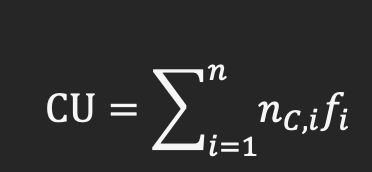

n is number of fluxes in the model, nc,i is the number of carbon atoms imported into intracellular compartments by the i-th flux and  is its flux rate. If this flux does not lead to any carbon uptake, the value of nc,i is zero.

% Inicializar una celda para almacenar los metabolitos implicados en las
% reacciones seleccionadas para obtener el consumo de carbono
metabolitosInvolucrados = cell(length(cuRxnsIDs), 1);

% Recorrer las reacciones seleccionadas
for i = 1:length(cuRxnsIDs)
    % Obtener el índice de la reacción actual en el modelo
    reactionIndex = find(strcmp(model.rxns, cuRxnsIDs{i}));
    
    % Obtener los metabolitos asociados a la reacción actual
    metabolitesInvolved = model.S(:, reactionIndex);

    % Filtrar los metabolitos que tienen coeficientes no nulos (participan en la reacción)
    activeMetabolites = find(metabolitesInvolved ~= 0);

    % Obtener los nombres de los metabolitos activos
    metaboliteNames = model.mets(activeMetabolites);
    
    % Guardar los metabolitos involucrados en la reacción en la celda
    metabolitosInvolucrados{i} = metaboliteNames;
end

% Guardar el archivo con los metabolitos involucrados en las reacciones seleccionadas
%save('metabolitos_involucrados_seleccionados.mat', 'metabolitosInvolucrados');
%disp('Los metabolitos involucrados en las reacciones seleccionadas han sido guardados correctamente.');

## **1.Calcular valores de flujos máximos de biomasa y atp, para obtener un rango de valores**


% Cambiar la reacción objetivo a la producción de biomasa
model1= model;
model1 = changeObjective(model1, tpHydrolysisRxn, 1);  

% Optimizar el modelo para maximizar la producción de biomasa
FATPHydrolysisMax = optimizeCbModel(model1).f;

% Mostrar el valor máximo alcanzado
fprintf('Máximo flujo de atp: %.2f\n', FATPHydrolysisMax);

Máximo flujo de atp: 1000.00



% Maximizar producción de biomasa
% Cambiar la reacción objetivo a la producción de biomasa
model2 = model;
model2 = changeObjective(model, biomassRxn, 1);

% Optimizar el modelo para maximizar la producción de biomasa
FBiomassMax = optimizeCbModel(model2).f;

% Mostrar el valor máximo alcanzado
fprintf('Máximo flujo de biomasa: %.2f\n', FBiomassMax);

Máximo flujo de biomasa: 730.70


% Calculando este ultimo objetivo tenemos en el modelo como objetivo
% biomasa

## **2. Crear n combinaciones de (ebiomass, eAtp)  en la region de [0,fmaxbiomass]*[0,fmaxatp] con Latin Hypercube Sampling**

El Latin Hypercube sampling es un metodo de muestreo que busca una representacion buena y eficiente de posibles combinaciones.

**¿Cómo Funciona el Latin Hypercube Sampling?**

**División del Espacio de Muestra:**

Para cada variable (`e_Biomass` y `e_ATP`), se divide el rango de valores posibles en *n* intervalos (o segmentos) de igual tamaño. Rangos: [0, f_Biomass^max] y [0, f_ATP^max], cada variable será dividida en segmentos basados en el número de muestras (10000).

**Muestreo dentro de Intervalos:**

Dentro de cada intervalo, se selecciona un punto aleatorio. Esto se hace de tal manera que cada intervalo tenga exactamente un punto representado en la muestra. Por ejemplo, si se tienes10 intervalos, se seleccionará un punto aleatorio en cada uno de ellos, asegurando que todos los intervalos sean representados y que no se repita el muestreo en el mismo intervalo.

**Combinación de Variables:**

Se combinan aleatoriamente los puntos seleccionados de cada variable para crear una serie de combinaciones. Esto asegura que las combinaciones de valores de diferentes variables sean representativas del espacio total.

**Creación de la Muestra:**

Al final del proceso, tendrás un conjunto de combinaciones que cubren de manera uniforme el espacio de entrada definido por el rango de ambas variables.

**Ventajas del LHS:**

Representación: Permite cubrir de manera más uniforme el espacio de muestra, lo que puede conducir a simulaciones más precisas al evitar la concentración de puntos en ciertas áreas.

Eficiencia: Requiere menos muestras para lograr una representación similar a la que se obtendría con muestreo aleatorio simple, lo que puede ser especialmente útil en simulaciones costosas.

Control sobre el diseño: Proporciona un diseño más estructurado que ayuda a evitar el sesgo en la selección de puntos.

% Calculo del conjunto de soluciones de pareto 
% Inicializar las variables
numSamples = 1000;  % Número de muestras
epsilonCombinations = lhsdesign(numSamples, 2); % Muestreo Latino Hiper cúbico
epsilonCombinations(:, 1) = epsilonCombinations(:, 1) * FBiomassMax; % Escalar al rango de biomasa
epsilonCombinations(:, 2) = epsilonCombinations(:, 2) * FATPHydrolysisMax; % Escalar al rango de ATP

% Inicializar arrays para almacenar las soluciones de Pareto
biomassSolutions = NaN(numSamples, 1);
ATPsolutions = NaN(numSamples, 1);
CUsolutions = NaN(numSamples, 1);
CU = NaN(numSamples, 1); % Inicializar CU

% Iterar sobre las combinaciones de ε
for i = 1:numSamples
    eBiomass = epsilonCombinations(i, 1);
    eATP = epsilonCombinations(i, 2);
    
    model_temp = model;
    changeObjective(model_temp, biomassRxn, 1);

    % Añadir restricciones de ε al modelo
    model_temp = changeRxnBounds(model, biomassRxn, eBiomass, 'l'); % f_Biomass >= e_Biomass
    model_temp = changeRxnBounds(model_temp, tpHydrolysisRxn, eATP, 'l'); % f_ATP >= e_ATP

    % Resolver el modelo para obtener los flujos
    solution = optimizeCbModel(model_temp);
    
    % Verificar si la solución es óptima
    if solution.stat == 1
        % Obtener flujos de biomasa y ATP
        biomassSolutions(i) = solution.x(find(strcmp(model.rxns, biomassRxn))); 
        ATPsolutions(i) = solution.x(find(strcmp(model.rxns, tpHydrolysisRxn))); 

        % Calcular el flujo de consumo de carbono (CU)
        CUfluxes = zeros(length(cuRxnsIDs), 1);
        Numatomos = zeros(length(cuRxnsIDs), 1);

        for j = 1:length(cuRxnsIDs)
            reactionIndex = find(strcmp(model.rxns, cuRxnsIDs{j}));  
            CUfluxes(j) = solution.x(reactionIndex); % Flujo de la reacción

            % Obtener el número de átomos de carbono
            % Aqui se manda a llamar countCarbons 
            atom_met = metabolitosInvolucrados{j};
            idx = find(strcmp(model.mets, atom_met));

            if ~isempty(idx)
                formula = model.metFormulas{idx};
                Numatomos(j) = countCarbons(formula);
            end
        end

        % Calcular el valor de CU
        CU(i) = sum(Numatomos .* CUfluxes);
        CUsolutions(i) = CU(i);
    else
        disp(['Modelo no factible para εBiomasa = ' num2str(eBiomass) ', εATP = ' num2str(eATP)]);
    end
end

 

MSK_RES_OK


Modelo no factible para εBiomasa = 694.3625, εATP = 907.8754


 

MSK_RES_OK


Modelo no factible para εBiomasa = 676.4613, εATP = 960.9205


 

MSK_RES_OK


Modelo no factible para εBiomasa = 637.2889, εATP = 851.0596


 

MSK_RES_OK


Modelo no factible para εBiomasa = 704.5667, εATP = 548.4363


 

MSK_RES_OK


Modelo no factible para εBiomasa = 698.2689, εATP = 418.4286


 

MSK_RES_OK


Modelo no factible para εBiomasa = 556.3061, εATP = 957.7524


 

MSK_RES_OK


Modelo no factible para εBiomasa = 617.0456, εATP = 590.3471


 

MSK_RES_OK


Modelo no factible para εBiomasa = 686.6649, εATP = 237.3881


 

MSK_RES_OK


Modelo no factible para εBiomasa = 728.4496, εATP = 226.795


 

MSK_RES_OK


Modelo no factible para εBiomasa = 691.8892, εATP = 756.0227


OPTIMAL


 

MSK_RES_OK


Modelo no factible para εBiomasa = 641.5584, εATP = 761.6939


 

MSK_RES_OK


Modelo no factible para εBiomasa = 716.6824, εATP = 944.6765


 

MSK_RES_OK


Modelo no factible para εBiomasa = 728.5552, εATP = 412.6355


 

MSK_RES_OK


Modelo no factible para εBiomasa = 713.8745, εATP = 754.5272


 

MSK_RES_OK


Modelo no factible para εBiomasa = 643.0992, εATP = 460.3676


 

MSK_RES_OK


Modelo no factible para εBiomasa = 663.1561, εATP = 372.0025


 

MSK_RES_OK


Modelo no factible para εBiomasa = 628.4574, εATP = 734.1755


 

MSK_RES_OK


Modelo no factible para εBiomasa = 620.9685, εATP = 706.7885


 

MSK_RES_OK


Modelo no factible para εBiomasa = 674.8501, εATP = 626.7239


 

MSK_RES_OK


Modelo no factible para εBiomasa = 660.5756, εATP = 592.9818


 

MSK_RES_OK


Modelo no factible para εBiomasa = 634.3959, εATP = 849.8506


 

MSK_RES_OK


Modelo no factible para εBiomasa = 617.5278, εATP = 623.6585


 

MSK_RES_OK


Modelo no factible para εBiomasa = 703.0336, εATP = 982.1652


 

MSK_RES_OK


Modelo no factible para εBiomasa = 665.3061, εATP = 594.3889


 

MSK_RES_OK


Modelo no factible para εBiomasa = 720.0354, εATP = 566.4918


 

MSK_RES_OK


Modelo no factible para εBiomasa = 652.6009, εATP = 509.5554


 

MSK_RES_OK


Modelo no factible para εBiomasa = 591.7453, εATP = 828.1022


OPTIMAL


 

MSK_RES_OK


Modelo no factible para εBiomasa = 679.3293, εATP = 205.1563


 

MSK_RES_OK


Modelo no factible para εBiomasa = 676.9084, εATP = 506.7841


 

MSK_RES_OK


Modelo no factible para εBiomasa = 717.5058, εATP = 479.2031


 

MSK_RES_OK


Modelo no factible para εBiomasa = 667.4152, εATP = 252.7552


 

MSK_RES_OK


Modelo no factible para εBiomasa = 659.6787, εATP = 285.1511


 

MSK_RES_OK


Modelo no factible para εBiomasa = 636.7716, εATP = 933.702


 

MSK_RES_OK


Modelo no factible para εBiomasa = 730.1537, εATP = 526.4661


OPTIMAL


 

MSK_RES_OK


Modelo no factible para εBiomasa = 679.7285, εATP = 362.7257


 

MSK_RES_OK


Modelo no factible para εBiomasa = 614.2367, εATP = 717.9908


OPTIMAL


 

MSK_RES_OK


Modelo no factible para εBiomasa = 593.5895, εATP = 837.4113


 

MSK_RES_OK


Modelo no factible para εBiomasa = 583.5078, εATP = 994.9774


 

MSK_RES_OK


Modelo no factible para εBiomasa = 655.4893, εATP = 733.4748


 

MSK_RES_OK


Modelo no factible para εBiomasa = 673.4634, εATP = 541.617


 

MSK_RES_OK


Modelo no factible para εBiomasa = 610.0171, εATP = 795.7681


 

MSK_RES_OK


Modelo no factible para εBiomasa = 688.2012, εATP = 383.7905


 

MSK_RES_OK


Modelo no factible para εBiomasa = 698.5964, εATP = 254.1085


 

MSK_RES_OK


Modelo no factible para εBiomasa = 661.5397, εATP = 776.6081


 

MSK_RES_OK


Modelo no factible para εBiomasa = 595.7747, εATP = 697.9538


OPTIMAL


 

MSK_RES_OK


Modelo no factible para εBiomasa = 721.0552, εATP = 365.0676


 

MSK_RES_OK


Modelo no factible para εBiomasa = 627.8444, εATP = 522.9463


 

MSK_RES_OK


Modelo no factible para εBiomasa = 603.9263, εATP = 872.4962


 

MSK_RES_OK


Modelo no factible para εBiomasa = 714.8833, εATP = 802.0707


 

MSK_RES_OK


Modelo no factible para εBiomasa = 619.8007, εATP = 898.2231


 

MSK_RES_OK


Modelo no factible para εBiomasa = 685.6764, εATP = 709.2831


 

MSK_RES_OK


Modelo no factible para εBiomasa = 690.9843, εATP = 486.5387


 

MSK_RES_OK


Modelo no factible para εBiomasa = 700.2136, εATP = 884.5894


OPTIMAL


 

MSK_RES_OK


Modelo no factible para εBiomasa = 690.469, εATP = 676.6497


 

MSK_RES_OK


Modelo no factible para εBiomasa = 689.5108, εATP = 912.0093


 

MSK_RES_OK


Modelo no factible para εBiomasa = 685.1722, εATP = 172.3318


OPTIMAL


 

MSK_RES_OK


Modelo no factible para εBiomasa = 672.5373, εATP = 210.7872


 

MSK_RES_OK


Modelo no factible para εBiomasa = 636.1578, εATP = 695.781


OPTIMAL


 

MSK_RES_OK


Modelo no factible para εBiomasa = 727.6122, εATP = 746.6958


 

MSK_RES_OK


Modelo no factible para εBiomasa = 723.2349, εATP = 793.1609


 

MSK_RES_OK


Modelo no factible para εBiomasa = 602.4334, εATP = 862.9945


 

MSK_RES_OK


Modelo no factible para εBiomasa = 724.7328, εATP = 222.3882


 

MSK_RES_OK


Modelo no factible para εBiomasa = 708.1147, εATP = 452.6977


 

MSK_RES_OK


Modelo no factible para εBiomasa = 669.7117, εATP = 642.793


 

MSK_RES_OK


Modelo no factible para εBiomasa = 671.8534, εATP = 442.8948


 

MSK_RES_OK


Modelo no factible para εBiomasa = 708.9225, εATP = 351.9427


 

MSK_RES_OK


Modelo no factible para εBiomasa = 696.7314, εATP = 573.5878


OPTIMAL


 

MSK_RES_OK


Modelo no factible para εBiomasa = 729.7942, εATP = 278.8418


 

MSK_RES_OK


Modelo no factible para εBiomasa = 647.3317, εATP = 615.5278


 

MSK_RES_OK


Modelo no factible para εBiomasa = 668.5771, εATP = 494.2136


OPTIMAL


 

MSK_RES_OK


Modelo no factible para εBiomasa = 703.6776, εATP = 337.563


 

MSK_RES_OK


Modelo no factible para εBiomasa = 646.4402, εATP = 707.3264


 

MSK_RES_OK


Modelo no factible para εBiomasa = 633.0342, εATP = 947.3227


 

MSK_RES_OK


Modelo no factible para εBiomasa = 629.2524, εATP = 747.6817


 

MSK_RES_OK


Modelo no factible para εBiomasa = 615.3744, εATP = 662.3406


 

MSK_RES_OK


Modelo no factible para εBiomasa = 700.8018, εATP = 276.4578


 

MSK_RES_OK


Modelo no factible para εBiomasa = 682.7879, εATP = 964.4254


 

MSK_RES_OK


Modelo no factible para εBiomasa = 613.0116, εATP = 767.2728


 

MSK_RES_OK


Modelo no factible para εBiomasa = 618.9604, εATP = 632.0375


 

MSK_RES_OK


Modelo no factible para εBiomasa = 723.8812, εATP = 413.6375


 

MSK_RES_OK


Modelo no factible para εBiomasa = 700.0055, εATP = 269.5361


 

MSK_RES_OK


Modelo no factible para εBiomasa = 686.9603, εATP = 162.0291


 

MSK_RES_OK


Modelo no factible para εBiomasa = 694.0594, εATP = 154.1576


 

MSK_RES_OK


Modelo no factible para εBiomasa = 697.4381, εATP = 891.4428


 

MSK_RES_OK


Modelo no factible para εBiomasa = 644.0054, εATP = 971.9057


 

MSK_RES_OK


Modelo no factible para εBiomasa = 709.7036, εATP = 100.1801


OPTIMAL


 

MSK_RES_OK


Modelo no factible para εBiomasa = 683.3113, εATP = 673.1196


 

MSK_RES_OK


Modelo no factible para εBiomasa = 713.9456, εATP = 437.881


 

MSK_RES_OK


Modelo no factible para εBiomasa = 578.9131, εATP = 843.1045


 

MSK_RES_OK


Modelo no factible para εBiomasa = 721.9691, εATP = 243.6694


 

MSK_RES_OK


Modelo no factible para εBiomasa = 637.9139, εATP = 832.8202


 

MSK_RES_OK


Modelo no factible para εBiomasa = 715.9565, εATP = 808.241


 

MSK_RES_OK


Modelo no factible para εBiomasa = 678.2655, εATP = 769.7127


 

MSK_RES_OK


Modelo no factible para εBiomasa = 658.26, εATP = 732.5561


 

MSK_RES_OK


Modelo no factible para εBiomasa = 623.4316, εATP = 790.9359


 

MSK_RES_OK


Modelo no factible para εBiomasa = 631.1841, εATP = 589.265


 

MSK_RES_OK


Modelo no factible para εBiomasa = 710.7917, εATP = 403.5071


 

MSK_RES_OK


Modelo no factible para εBiomasa = 633.522, εATP = 863.0511


 

MSK_RES_OK


Modelo no factible para εBiomasa = 721.6606, εATP = 645.9819


 

MSK_RES_OK


Modelo no factible para εBiomasa = 626.3838, εATP = 942.7181


 

MSK_RES_OK


Modelo no factible para εBiomasa = 613.7774, εATP = 861.1069


 

MSK_RES_OK


Modelo no factible para εBiomasa = 635.5317, εATP = 817.3949


 

MSK_RES_OK


Modelo no factible para εBiomasa = 688.6439, εATP = 119.702


 

MSK_RES_OK


Modelo no factible para εBiomasa = 695.3736, εATP = 114.1681


 

MSK_RES_OK


Modelo no factible para εBiomasa = 680.8583, εATP = 739.9938


 

MSK_RES_OK


Modelo no factible para εBiomasa = 577.9198, εATP = 943.3628


 

MSK_RES_OK


Modelo no factible para εBiomasa = 647.7506, εATP = 619.4647


 

MSK_RES_OK


Modelo no factible para εBiomasa = 666.4181, εATP = 588.4334


 

MSK_RES_OK


Modelo no factible para εBiomasa = 599.0983, εATP = 958.185


 

MSK_RES_OK


Modelo no factible para εBiomasa = 701.5998, εATP = 711.8364


 

MSK_RES_OK


Modelo no factible para εBiomasa = 707.022, εATP = 988.2119


 

MSK_RES_OK


Modelo no factible para εBiomasa = 675.7935, εATP = 823.8019


 

MSK_RES_OK


Modelo no factible para εBiomasa = 725.3236, εATP = 167.6274


 

MSK_RES_OK


Modelo no factible para εBiomasa = 711.1705, εATP = 459.8289


 

MSK_RES_OK


Modelo no factible para εBiomasa = 607.5913, εATP = 631.7394


 

MSK_RES_OK


Modelo no factible para εBiomasa = 717.5489, εATP = 826.5635


 

MSK_RES_OK


Modelo no factible para εBiomasa = 696.1936, εATP = 586.5018


 

MSK_RES_OK


Modelo no factible para εBiomasa = 663.8786, εATP = 951.9315


 

MSK_RES_OK


Modelo no factible para εBiomasa = 623.0365, εATP = 726.5993


 

MSK_RES_OK


Modelo no factible para εBiomasa = 712.3915, εATP = 829.6554


 

MSK_RES_OK


Modelo no factible para εBiomasa = 632.0579, εATP = 896.4763


 

MSK_RES_OK


Modelo no factible para εBiomasa = 726.3459, εATP = 366.7683


OPTIMAL


 

MSK_RES_OK


Modelo no factible para εBiomasa = 603.4229, εATP = 674.147


 

MSK_RES_OK


Modelo no factible para εBiomasa = 670.9606, εATP = 737.8123


 

MSK_RES_OK


Modelo no factible para εBiomasa = 641.2925, εATP = 762.9355


 

MSK_RES_OK


Modelo no factible para εBiomasa = 666.3965, εATP = 478.806


 

MSK_RES_OK


Modelo no factible para εBiomasa = 658.975, εATP = 441.2245


 

MSK_RES_OK


Modelo no factible para εBiomasa = 705.5086, εATP = 207.7906


 

MSK_RES_OK


Modelo no factible para εBiomasa = 684.339, εATP = 507.5939


 

MSK_RES_OK


Modelo no factible para εBiomasa = 719.3745, εATP = 560.0498


 

MSK_RES_OK


Modelo no factible para εBiomasa = 706.4075, εATP = 559.67


 

MSK_RES_OK


Modelo no factible para εBiomasa = 707.7648, εATP = 565.8965


 

MSK_RES_OK


Modelo no factible para εBiomasa = 622.0084, εATP = 578.1498


 

MSK_RES_OK


Modelo no factible para εBiomasa = 718.5833, εATP = 174.7404


 

MSK_RES_OK


Modelo no factible para εBiomasa = 656.5024, εATP = 648.7093


 

MSK_RES_OK


Modelo no factible para εBiomasa = 712.5653, εATP = 939.2155


 

MSK_RES_OK


Modelo no factible para εBiomasa = 650.5456, εATP = 444.5403


 

MSK_RES_OK


Modelo no factible para εBiomasa = 725.6211, εATP = 871.3352


 

MSK_RES_OK


Modelo no factible para εBiomasa = 568.588, εATP = 900.4573


 

MSK_RES_OK


Modelo no factible para εBiomasa = 610.5495, εATP = 892.1365


 

MSK_RES_OK


Modelo no factible para εBiomasa = 642.8088, εATP = 497.4782


 

MSK_RES_OK


Modelo no factible para εBiomasa = 702.8378, εATP = 253.0741


 

MSK_RES_OK


Modelo no factible para εBiomasa = 673.7538, εATP = 738.1359



% Filtrar soluciones factibles (sin NaN)
validIdx = ~isnan(biomassSolutions) & ~isnan(ATPsolutions) & ~isnan(CUsolutions);

% Estratificación para seleccionar m1 y m2 valores de CU y ATP
m1 = min(10, length(unique(CUsolutions(validIdx)))); % Número máximo de muestras para CU
m2 = min(10, length(unique(ATPsolutions(validIdx)))); % Número máximo de muestras para ATP

% Muestreo estratificado
CU_min = min(CUsolutions(validIdx));
CU_max = max(CUsolutions(validIdx));
ATP_min = min(ATPsolutions(validIdx));
ATP_max = max(ATPsolutions(validIdx));

CUsamples = linspace(CU_min, CU_max, m1);
ATPsamples = linspace(ATP_min, ATP_max, m2);

% Segunda fase de optimización con restricciones fijadas
for i = 1:m1
    for j = 1:m2
        % Fijar restricciones de CU y ATP
        model_temp = changeRxnBounds(model, cuRxnsIDs, CUsamples(i), 'b'); % CU fijado
        model_temp = changeRxnBounds(model_temp, tpHydrolysisRxn, ATPsamples(j), 'b'); % ATP fijado
        
        % Optimizar modelo
        solution = optimizeCbModel(model_temp);

        % Verificar si la solución es óptima
        if solution.stat == 1
            biomassFlux = solution.x(find(strcmp(model.rxns, biomassRxn)));
        end
    end
end

 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


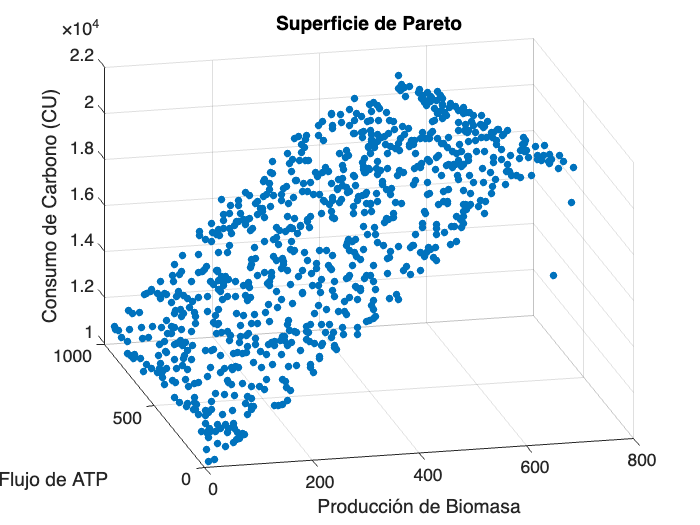


% % Mostrar resultados
figure;
scatter3(biomassSolutions(validIdx), ATPsolutions(validIdx), CUsolutions(validIdx), 'filled');

xlabel('Producción de Biomasa', 'FontSize', 16);
ylabel('Flujo de ATP', 'FontSize', 16);
zlabel('Consumo de Carbono (CU)', 'FontSize', 16);
title('Superficie de Pareto', 'FontSize', 18);

ax = gca;
ax.FontSize = 14;
grid on;

%% Calculo de soluciones de pareto con inhibición de enzimas
% Variables para inhibición de enzimas
inhibitionFactor = 0;  % Supuesto: inhibición reduce la actividad al 50%

% Enzimas a inhibir
enzymes = {'HMR_9040'}; % Enzimas específicas a inhibir (Leucina)

model_temp2 = model;
model_temp2 = changeObjective(model_temp2,biomassRxn,1)

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199


    % Aplicar inhibición de enzimas sobre las reacciones
    for k = 1:length(enzymes)  % Iterar sobre las enzimas a inhibir
        enzymeID = enzymes{k};
        reactionIndex = find(strcmp(model.rxns, enzymeID));  % Buscar el índice de la reacción de la enzima
        
        if ~isempty(reactionIndex)
            model_temp2 = changeRxnBounds(model_temp2, enzymeID, inhibitionFactor, 'u'); % Inhibición de enzima
        end
    end

% Resolver el modelo para obtener los flujos con inhibición de enzimas
FBiomassMax_inhibeded = optimizeCbModel(model_temp2).f

FBiomassMax_inhibeded = 1.4749e-09



model_temp2 = changeObjective(model, tpHydrolysisRxn, 1);
FATPHydrolysisMax_inhibeded = optimizeCbModel(model_temp2).f 

FATPHydrolysisMax_inhibeded = 1.0000e+03


% combinaciones de ε por LHS
epsilonCombinations = lhsdesign(numSamples, 2); % Muestreo Latino Hiper cúbico
epsilonCombinations(:, 1) = epsilonCombinations(:, 1) * FBiomassMax_inhibeded; % Escalar al rango de biomasa
epsilonCombinations(:, 2) = epsilonCombinations(:, 2) * FATPHydrolysisMax_inhibeded; % Escalar al rango de ATP

% Iterar nuevamente sobre las combinaciones de ε
biomassSolutions_inhibited = NaN(numSamples, 1);
ATPsolutions_inhibited = NaN(numSamples, 1);
CUsolutions_inhibited = NaN(numSamples, 1);


for i = 1:numSamples
    eBiomass = epsilonCombinations(i, 1);
    eATP = epsilonCombinations(i, 2);
    
    model_temp2 = model;
    model_temp2 = changeObjective(model_temp2,biomassRxn,1)
    % Añadir restricciones de ε al modelo
    model_temp2 = changeRxnBounds(model, biomassRxn, eBiomass, 'l'); % f_Biomass >= e_Biomass
    model_temp2 = changeRxnBounds(model_temp2, tpHydrolysisRxn, eATP, 'l'); % f_ATP >= e_ATP

    % Aplicar inhibición de enzimas sobre las reacciones
    for k = 1:length(enzymes)  % Iterar sobre las enzimas a inhibir
        enzymeID = enzymes{k};
        reactionIndex = find(strcmp(model.rxns, enzymeID));  % Buscar el índice de la reacción de la enzima
        
        if ~isempty(reactionIndex)
            model_temp2 = changeRxnBounds(model_temp2, enzymeID, inhibitionFactor, 'u'); % Inhibición de enzima
        end
    end

    % Resolver el modelo para obtener los flujos con inhibición de enzimas
    solution = optimizeCbModel(model_temp2);
    
    % Verificar si la solución es óptima
    if solution.stat == 1
        % Obtener flujos de biomasa y ATP
        biomassSolutions_inhibited(i) = solution.x(find(strcmp(model.rxns, biomassRxn))); 
        ATPsolutions_inhibited(i) = solution.x(find(strcmp(model.rxns, tpHydrolysisRxn))); 

        % Calcular el flujo de consumo de carbono (CU)
        CUfluxes = zeros(length(cuRxnsIDs), 1);
        Numatomos = zeros(length(cuRxnsIDs), 1);

        for j = 1:length(cuRxnsIDs)
            reactionIndex = find(strcmp(model.rxns, cuRxnsIDs{j}));  
            CUfluxes(j) = solution.x(reactionIndex); % Flujo de la reacción

            % Obtener el número de átomos de carbono
            atom_met = metabolitosInvolucrados{j};
            idx = find(strcmp(model.mets, atom_met));

            if ~isempty(idx)
                formula = model.metFormulas{idx};
                Numatomos(j) = countCarbons(formula);
            end
        end

        % Calcular el valor de CU
        CU(i) = sum(Numatomos .* CUfluxes);
        CUsolutions_inhibited(i) = CU(i);
    else
        disp(['Modelo no factible para εBiomasa = ' num2str(eBiomass) ', εATP = ' num2str(eATP)]);
    end
end

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

OPTIMAL


model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

OPTIMAL


model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

OPTIMAL


model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

OPTIMAL


model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

OPTIMAL


model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

OPTIMAL


model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199

model_temp2 = struct with fields:
                  S: [5458×4301 double]
               mets: {5458×1 cell}
                  b: [5458×1 double]
             csense: [5458×1 char]
               rxns: {4301×1 cell}
                 lb: [4301×1 double]
                 ub: [4301×1 double]
                  c: [4301×1 double]
          osenseStr: 'max'
              genes: {}
              rules: {4301×1 cell}
          compNames: {9×1 cell}
              comps: {9×1 cell}
        metFormulas: {5458×1 cell}
           metNames: {5458×1 cell}
           metNotes: {5458×1 cell}
        metSBOTerms: {5458×1 cell}
           rxnNames: {4301×1 cell}
        rxnSBOTerms: {4301×1 cell}
         subSystems: {4301×1 cell}
        description: 'iBreastCancer1771.xml'
       modelVersion: [1×1 struct]
          modelName: 'Automatically generated model for Breast - breast cancer'
            modelID: 'iBreastCancer1771'
    modelAnnotation: '<annotation>↵  <rdf:RDF xmlns:rdf="http://www.w3.org/199


% Filtrar soluciones factibles (sin NaN)
validIdx = ~isnan(biomassSolutions_inhibited) & ~isnan(ATPsolutions_inhibited) & ~isnan(CUsolutions_inhibited);

% Estratificación para seleccionar m1 y m2 valores de CU y ATP
m1 = min(10, length(unique(CUsolutions_inhibited(validIdx)))); % Número máximo de muestras para CU
m2 = min(10, length(unique(ATPsolutions_inhibited(validIdx)))); % Número máximo de muestras para ATP

% Muestreo estratificado
CU_min = min(CUsolutions_inhibited(validIdx));
CU_max = max(CUsolutions_inhibited(validIdx));
ATP_min = min(ATPsolutions_inhibited(validIdx));
ATP_max = max(ATPsolutions_inhibited(validIdx));

CUsamples = linspace(CU_min, CU_max, m1);
ATPsamples = linspace(ATP_min, ATP_max, m2);

% Segunda fase de optimización con restricciones fijadas
for i = 1:m1
    for j = 1:m2
        % Fijar restricciones de CU y ATP
        model_temp2 = changeRxnBounds(model, cuRxnsIDs, CUsamples(i), 'b'); % CU fijado
        model_temp2 = changeRxnBounds(model_temp2, tpHydrolysisRxn, ATPsamples(j), 'b'); % ATP fijado
        
        % Optimizar modelo
        solution = optimizeCbModel(model_temp2);

        % Verificar si la solución es óptima
        if solution.stat == 1
            biomassFlux = solution.x(find(strcmp(model.rxns, biomassRxn)));
        end
    end
end

 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


 

MSK_RES_OK


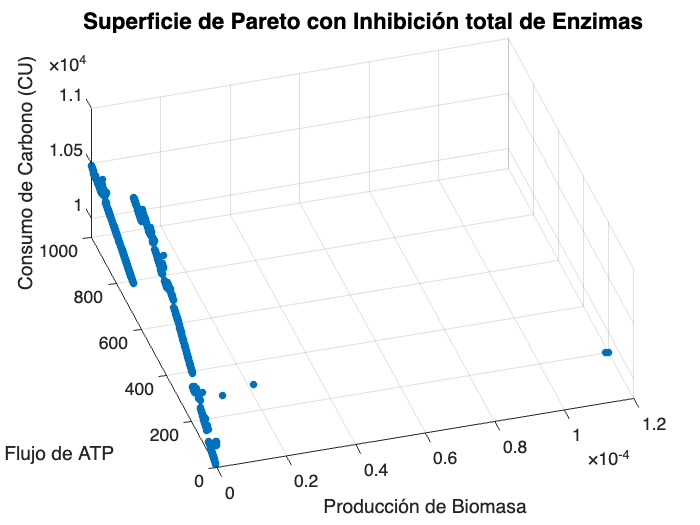


% % Mostrar resultados
figure;
scatter3(biomassSolutions_inhibited(validIdx), ATPsolutions_inhibited(validIdx), CUsolutions_inhibited(validIdx), 'filled');

xlabel('Producción de Biomasa', 'FontSize', 16);
ylabel('Flujo de ATP', 'FontSize', 16);
zlabel('Consumo de Carbono (CU)', 'FontSize', 16);
title('Superficie de Pareto', 'FontSize', 18);

ax = gca;
ax.FontSize = 14;
grid on;
title('Superficie de Pareto con Inhibición total de Enzima', 'FontSize', 18);

%% Calculo de Pareto Deviation Score (PDS)

% % Lista de reacciones y metabolitos involucrados
% rxnMetabolites = {
%     'HMR_9034', {'glucose[x]'},
%     'HMR_9039', {'isoleucine[x]'},
%     'HMR_9040', {'leucine[x]'},
%     'HMR_9041', {'lysine[x]'},
%     'HMR_9042', {'methionine[x]'},
%     'HMR_9043', {'phenylalanine[x]'},
%     'HMR_9044', {'threonine[x]'},
%     'HMR_9045', {'tryptophan[x]'},
%     'HMR_9046', {'valine[x]'},
%     'HMR_9061', {'alanine[x]'},
%     'HMR_9062', {'asparagine[x]'},
%     'HMR_9063', {'glutamine[x]'},
%     'HMR_9064', {'tyrosine[x]'},
%     'HMR_9066', {'arginine[x]'},
%     'HMR_9067', {'glycine[x]'},
%     'HMR_9068', {'proline[x]'},
%     'HMR_9069', {'serine[x]'},
%     'HMR_9070', {'aspartate[x]'},
%     'HMR_9071', {'glutamate[x]'},
%     'HMR_9133', {'pyruvate[x]'},
%     'HMR_9083', {'choline[x]'},
%     'HMR_9085', {'glycerol[x]'},
%     'HMR_9102', {'lactose[x]'},
%     'HMR_9109', {'biotin[x]'},
%     'HMR_9145', {'pantothenate[x]'},
%     'HMR_9158', {'ascorbate[x]'},
%     'HMR_9159', {'thiamin[x]'},
%     'HMR_9292', {'L-carnitine[x]'}
% };
% 
% % Identificar los índices de las reacciones en el modelo
% rxnIndexes = find(ismember(model.rxns, cuRxnsIDs));
% 
% % Resolver el modelo con FBA
% FBAsolution = optimizeCbModel(model);
% 
% % Obtener los flujos de todas las reacciones
% fluxes = FBAsolution.x;
% 
% % Inicializar rxnIndexes
% rxnIndexes = [];
% for i = 1:length(cuRxnsIDs)
%     idx = find(strcmp(model.rxns, cuRxnsIDs{i}));
%     if ~isempty(idx)
%         rxnIndexes = [rxnIndexes; idx];
%     else
%         disp(['Reacción no encontrada en el modelo: ' cuRxnsIDs{i}]);
%     end
% end
% 
% % Verificar límites de índices
% if max(rxnIndexes) > length(fluxes)
%     error('Algunos índices exceden el tamaño de los flujos. Verifica rxnIndexes.');
% end
% 
% % Obtener los flujos asociados a estas reacciones
% fluxesOfInterest = fluxes(rxnIndexes);
% 
% % Mostrar los flujos relevantes
% disp('Flujos asociados a las reacciones de interés:');
% for i = 1:length(rxnIndexes)
%     disp(['Reacción: ' cuRxnsIDs{i} ', Flujo: ' num2str(fluxesOfInterest(i))]);
% end
